## Assignment #3

### 1) Ziegler Nichols First Method (First Order Plant)

The plant is G(s) = e^(-Ls) / (Ts+1)

clc
clear all

%defining plant
L = 0.1;
T = 1;
s = tf('s');
G1 = exp(-L*s) / (T*s + 1)

G1 =
 
                  1
  exp(-0.1*s) * -----
                s + 1
 
Continuous-time transfer function.



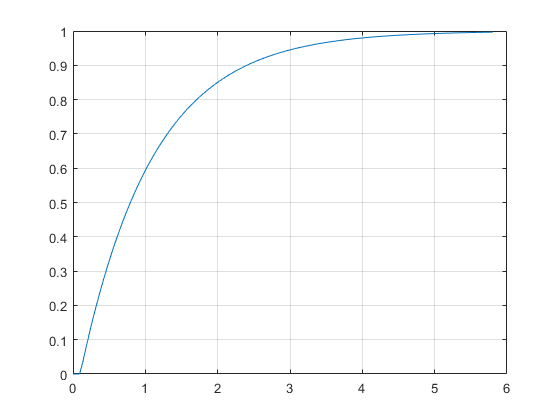


[openLoopResponse,t] = step(G1);

figure;
plot(t,openLoopResponse)
grid;


L = 0.1;
T = 1.2;

Kp = 1.2*T/L

Kp = 14.4000

Ti = 2*L

Ti = 0.2000

Td = 0.5*L

Td = 0.0500

Ki = Kp/Ti

Ki = 72.0000

Kd = Td*Kp

Kd = 0.7200

Gc1 = Kp+Ki/s+Kd*s

Gc1 =
 
  0.72 s^2 + 14.4 s + 72
  ----------------------
            s
 
Continuous-time transfer function.



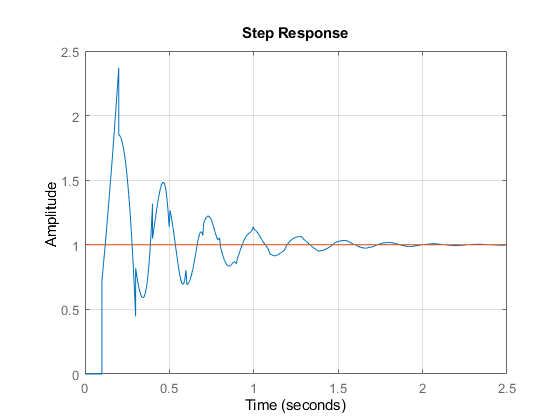


sys1 = feedback(Gc1*G1, 1);
figure; step(sys1,tf(1,1) ); grid;


% Analytic Method to find tau and L
maxResponse = max(openLoopResponse);
indxFor063 = find(openLoopResponse>=maxResponse*0.63);
indxFor028 = find(openLoopResponse>=maxResponse*0.28);

tau_analytic = 1.5*(t(indxFor063(1))-t(indxFor028(1)))

tau_analytic = 0.9671

L_analytic = t(indxFor063(1))-tau_analytic

L_analytic = 0.1382


Kp = 1.2*tau_analytic/L_analytic

Kp = 8.4000

Ti = 2*L_analytic

Ti = 0.2763

Td = 0.5*L_analytic

Td = 0.0691

Ki = Kp/Ti

Ki = 30.4006

Kd = Td*Kp

Kd = 0.5803

Gc1_analytic = Kp+Ki/s+Kd*s

Gc1_analytic =
 
  0.5803 s^2 + 8.4 s + 30.4
  -------------------------
              s
 
Continuous-time transfer function.



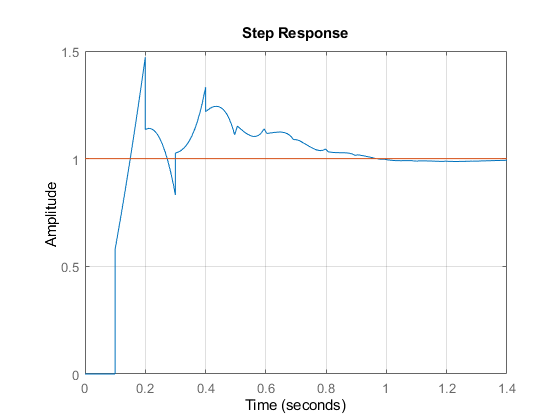


sys_analytic = feedback(Gc1_analytic*G1, 1);
figure; step(sys_analytic,tf(1,1) ); grid;

### 2) Ziegler Nichols First Method (Second Order Plant)

The plant is G(s) = 120 / (s+10)(s+12)

G2 = 120 / ((s+10)*(s+12))

G2 =
 
        120
  ----------------
  s^2 + 22 s + 120
 
Continuous-time transfer function.



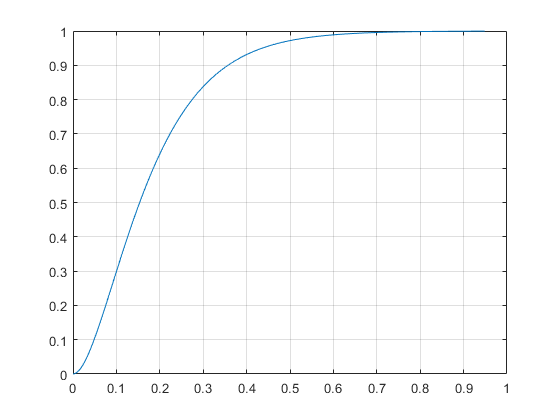

[openLoopResponse2,t2] = step(G2);

figure;
plot(t2,openLoopResponse2)
grid;


L = 0.025;
tau = 0.27-L;

Kp = 1.2*tau/L

Kp = 11.7600

Ti = 2*L

Ti = 0.0500

Td = 0.5*L

Td = 0.0125

Ki = Kp/Ti

Ki = 235.2000

Kd = Td*Kp

Kd = 0.1470

Gc2 = Kp+Ki/s+Kd*s

Gc2 =
 
  0.147 s^2 + 11.76 s + 235.2
  ---------------------------
               s
 
Continuous-time transfer function.



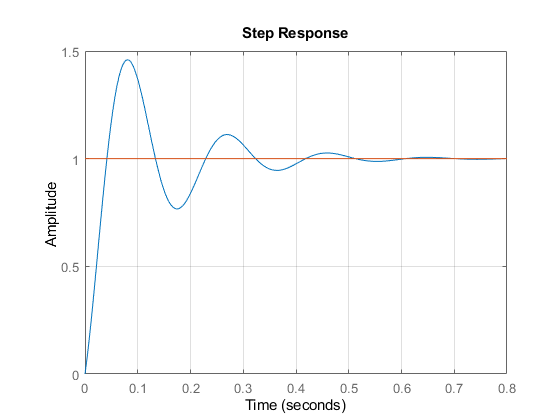


sys2 = feedback(Gc2*G2, 1);
figure; step(sys2,tf(1,1) ); grid;